clear

1014 

111321515  游思敏

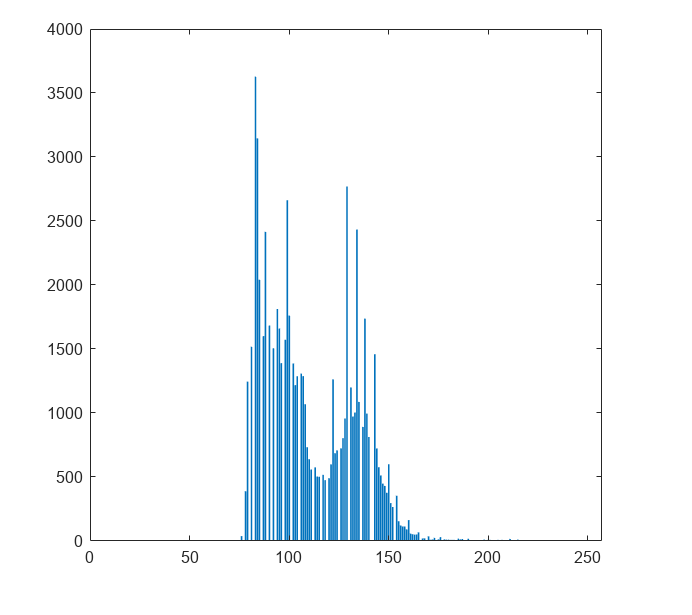

v = VideoReader("flyman512x512.avi");
i = 0 ;

bg = imread("flymanBG.jpg");
gbg = rgb2gray(bg);
dbg = double(gbg);

while hasFrame(v)
    video = readFrame(v);    
    gv = rgb2gray(video);
    dv = double(gv);
    bgremove = abs(dv - dbg);
    
    imshow((bgremove+255)/2, []), axis square;
    drawnow;
    i = i + 1;

end

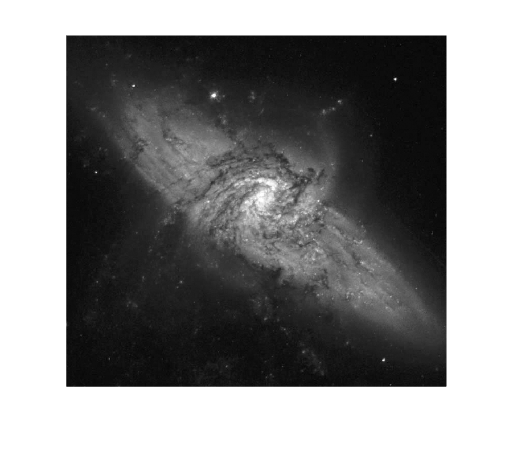

img = imread('./images_chapter_03/Fig3.30(a).jpg');
imgd = double(img);
i = 0;

while (i<16)
    t = rand(size(imgd));
    ave = imgd + t;
    imshow(ave, []);
    ave = ave/16;
    i = i+1;

end

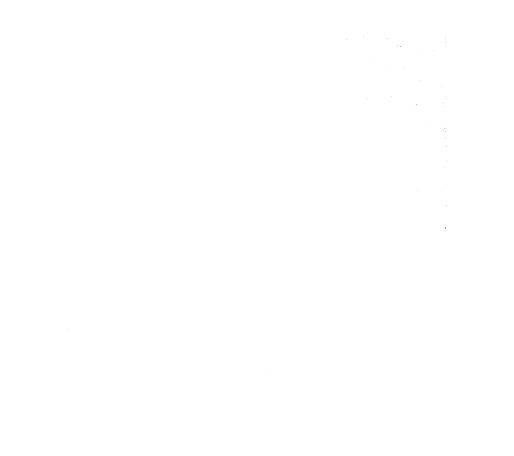

imshow(ave);

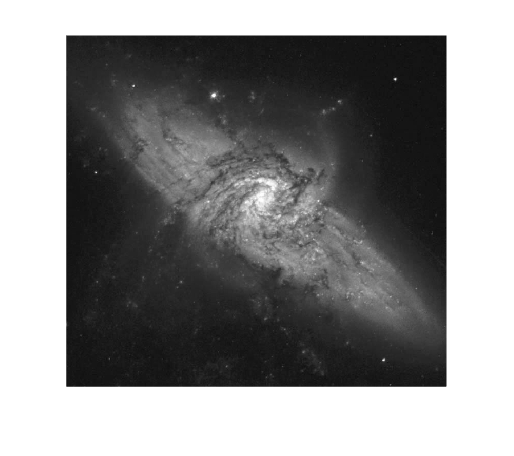


imshow(img);

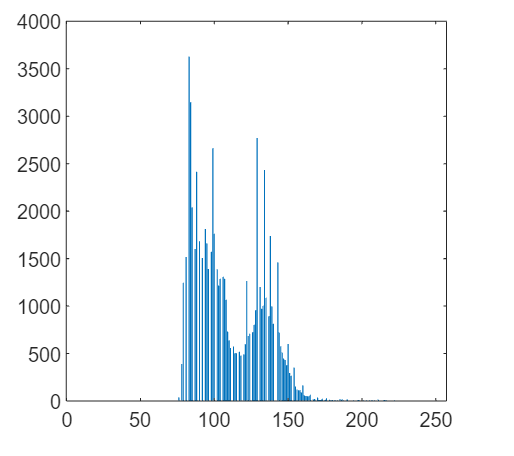

img = imread('pout.tif');
ret = myhist(img);
bar(ret);


function ret = myhist(I);
    ret = zeros(256, 1);
    [row, col] = size(I);
    for i=1:row
        for j=1:col
            ret(I(i,j)+1) = ret(I(i,j)+1)+1;
        end
    end
end